# Show Productive Structure Demo

Show the Productive Structure Info and the Flows Diagram  

#### Read Data Model

file='cgam_model.json';
data=ReadDataModel(file);

#### Get the Productive Structure Tables

res=ProductiveStructure(data);
printResults(res);

Flows Table

  Id  Key  From     To       Type     
---------------------------------------
   1  B1   ENV_R1   COMP_P1  RESOURCE 
   2  B2   COMP_P1  HEAT_F1  INTERNAL 
   3  B3   HEAT_P1  COMB_P1  INTERNAL 
   4  B4   COMB_P1  TURB_F1  INTERNAL 
   5  B5   TURB_F1  HEAT_F1  INTERNAL 
   6  B6   HEAT_P1  HRSG_F1  INTERNAL 
   7  B7   HRSG_F1  STCK_F1  INTERNAL 
   8  B8   ENV_R2   HRSG_P1  RESOURCE 
   9  B9   HRSG_P1  ENV_O1   OUTPUT   
  10  WN   TURB_P1  ENV_O2   OUTPUT   
  11  WC   TURB_P1  COMP_F1  INTERNAL 
  12  NG   ENV_R3   COMB_F1  RESOURCE 
  13  QG   STCK_P1  ENV_W1   WASTE    


Streams Table

  Id  Key      Definition  Type     
-------------------------------------
   1  COMB_F1  NG          FUEL     
   2  COMB_P1  B4-B3       PRODUCT  
   3  COMP_F1  WC          FUEL     
   4  COMP_P1  B2-B1       PRODUCT  
   5  TURB_F1  B4-B5       FUEL     
   6  TURB_P1  WC+WN       PRODUCT  
   7  HEAT_F1  B2+B5       FUEL     
   8  HEAT_P1  B6+B3       PRODUCT  
   9  HRSG_F1

#### Show Flows Diagram

Use the cResultsInfo method flowsDiagram to obtain the flows diagram

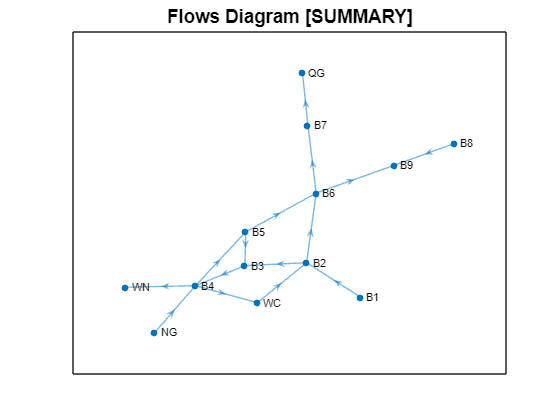

dg=ProductiveDiagram(data);
dg.showFlowsDiagram;